# **《科学》杂志上的电磁隐身衣演示**

**        2006年，美国《科学》杂志发表了Pendry等的论文《控制电磁场》。文中，作者首次提出了利用麦克斯韦方程组的协变性来控制电磁场的思路，并以此论文为基础，提出了变换光学（变换电磁学）的理论。由此，全球范围内关于电磁隐形的研究成为科研领域的热点。 Pendry提出的电磁隐形衣可以用如下的球坐标系下的坐标变换来描述： **


$$\begin{array}{l}
r^{\prime } =R_1 +\frac{R_2 -R_1 }{R_2 }r,~~\theta^{\prime } =\theta ,~~\varphi^{\prime } =\varphi \\
r=(r^{\prime } -R_1 )\frac{R_2 }{R_2 -R_1 },~~\theta =\theta^{\prime } ,~~\varphi =\varphi^{\prime } 
\end{array}$$


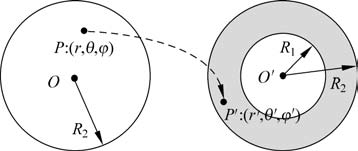

**        可以看出，该变换把O坐标系(Pendry称之为虚拟空间)下的一个半径为R2 的球形区域映射为O'系(物理空间)下内、外半径分别为R1和R2的一个球壳区域。由于麦克斯韦方程组的协变性，Pendry认为：对于这两个空间，电磁波的规律是一致的；两个空间中的电磁场分布通过简单的规律建立了联系；与虚拟空间中的空气不同，物理空间的球壳内，填充了各向异性的非均匀电磁材料；由于上述材料的存在，物理空间中的电磁波进入不到球壳内部囊括的球形区域，而球壳外部，电磁波不受影响。正因为如此，可以在隐形区域内部放置各种目标，但是外部观察者或者设备根本探测不到。**

**        Pendry给出了这种隐形材料的推导过程及设计结果，具体见参考文献[1]。使用MATLAB可以进行计算和仿真。 由仿真结果可以看出，该装置实现了较好的隐身效果，对外电场几乎没有扰动。**

**设置光线对应的参数区间和光线根数：**

clc
clear
tspan=[0 20];                      	%设置光线对应的参数区间
no_lines=30;                      	%设置光线根数

**计算单位球面所对应的空间坐标并绘制内外球面：**

a=2;                             	%隐形衣内径
b=4;                            	%隐形衣外径
[x,y,z]=sphere(100);                 	%计算单位球面所对应的空间坐标
surf(a*x,a*y,a*z);hold on;           	%绘制内部的球面，并设置叠加绘图模式
surf(b*x,b*abs(y),b*z);              	%绘制外部球面。由于使用了绝对值，仅绘制半球面

**设置光照和视角：**

shading interp;                      
light('Position',[-1,0,0]) ;              	%设置光照位置
lighting gouraud;                  	%设置光照模式
view(-40,17);                     	%设置视角

**计算入射点的坐标和角度：**

r0=1;                            	%入射点所在圆的半径为1
d=6;                             
c=sqrt(b^2-r0^2);                  	%入射点所在圆面到原点的距离
phi0=linspace(0,2*pi,no_lines);      	%在圆面上均匀选择30个点，作为入射点
theta0=pi-asin(r0/b);                	%计算入射点对应的theta角度
Y0=r0*cos(phi0);                  	%入射点的y坐标
Z0=r0*sin(phi0);                         	%入射点的z坐标
X0=linspace(-c,-c,no_lines);                 	%入射点的x坐标  

**绘制光线起始点的坐标：**

xx=linspace(-d,-d,no_lines); zz=Z0;yy=Y0;     	%光线起始点的坐标
for l=1:no_lines
line([X0(l),xx(l)],[Y0(l),yy(l)],[Z0(l),zz(l)],'color','g','linewidth',1.5);   %绘制每一根光线
end

**计算光线的方向分量和波矢：**

for lp=1:no_lines	
    x0=X0(lp);y0=Y0(lp); z0=Z0(lp);            	 %每根光线的入射点坐标
ny0=-sin(theta0)*cos(phi0(lp)); nx0=-cos(theta0);nz0=-sin(theta0)*sin(phi0(lp)); %方向分量
m=(2*a*b-a^2)/b^4;                        	%定义常数
h=1+ny0^2/nx0^2+nz0^2/nx0^2-m*y0^2*ny0^2/nx0^2-m*z0^2*(nz0^2/nx0^2)-2*m*x0*z0*(nz0/nx0)-2*m*y0*z0*(ny0*nz0/nx0^2)-m*x0^2-2*m*x0*y0*ny0/nx0;
%定义h   
g=-2*ny0^2/nx0^2-2*nz0^2/nx0^2+2*m*y0^2*ny0^2/nx0^2+2*m*z0^2*nz0^2/nx0^2+4*m*y0*z0*nz0*ny0/nx0^2+2*m*x0*y0*ny0/nx0+2*m*x0*z0*nz0/nx0;
%定义g   
u=ny0^2/nx0^2+nz0^2/nx0^2-m*y0^2*ny0^2/nx0^2-m*z0^2*(nz0^2/nx0^2)-2*m*y0*z0*(ny0*nz0/nx0^2)-1;
%定义u
kx0=(-g+sqrt(g^2-4*h*u))/(2*h);         %计算波矢的起始x分量
ky0=(ny0/nx0)*(kx0-1);                	%计算波矢的起始y分量
kz0=(nz0/nx0)*(kx0-1);               	%计算波矢的起始z分量
Yi=[x0 y0 z0 kx0 ky0 kz0];       	%起始矢量

**利用ode45函数进行计算：**

options = odeset('RelTol',1e-10,'AbsTol',[1e-10]);	%ode45函数的附加设置项
[T,Y] = ode45(@rayham,tspan,Yi,options);  	%利用ode45函数（求积分）进行计算
plot3(Y(:,1),Y(:,2),Y(:,3),'color','g','linewidth',1.5);	%绘制光线
end

** 绘制出射的光线：**

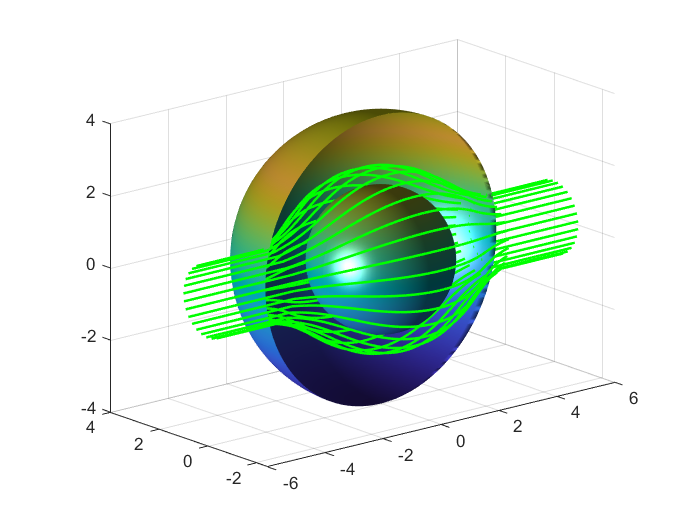

X0=linspace(c,c,no_lines);           	
xx=linspace(d,d,no_lines);zz=Z0;yy=Y0;
for l=1:no_lines
line([X0(l),xx(l)],[Y0(l),yy(l)],[Z0(l),zz(l)],'color','g','linewidth',1.5);
end
axis equal;                      	%设置三个方向等比例显示
set(gcf,'Visible','on');   	    %强制图片弹出显示

function dy = rayham(t,y);
    dy =zeros(6,1); 
    a=2;b=4;                             	%内外半径数值
    r=(y(1).^2+y(2).^2+y(3).^2).^(1/2);        	%球坐标系下矢径的大小
    s=y(1)*y(4)+y(2)*y(5)+y(3)*y(6);    	%定义波矢与矢径的点积
    dy(1) = y(4)-((2*a*r-a^2)/r^4)*s*y(1);     	%哈密顿方程组的前三个方程
    dy(2) = y(5)-((2*a*r-a^2)/r^4)*s*y(2);
    dy(3) = y(6)-((2*a*r-a^2)/r^4)*s*y(3);
		    %哈密顿方程组的后三个方程
    dy(4) = -((2*a*r-a^2)/r^4)*s*y(4)+((3*a*r-2*a^2)/r^6)*(s^2)*y(1)-((b/(b-a))^2)*((a*r-a^2)/r^4)*y(1);
    dy(4)=-dy(4);
    dy(5) = -((2*a*r-a^2)/r^4)*s*y(5)+((3*a*r-2*a^2)/r^6)*(s^2)*y(2)-((b/(b-a))^2)*((a*r-a^2)/r^4)*y(2);
    dy(5)=-dy(5);
    dy(6) = -((2*a*r-a^2)/r^4)*s*y(6)+((3*a*r-2*a^2)/r^6)*(s^2)*y(3)-((b/(b-a))^2)*((a*r-a^2)/r^4)*y(3);
    dy(6)=-dy(6);
end

- **参考文献：**

**                [1] J. B. Pendry *****et al. *****,Controlling Electromagnetic Fields.*****Science*****312,1780-1782(2006).**